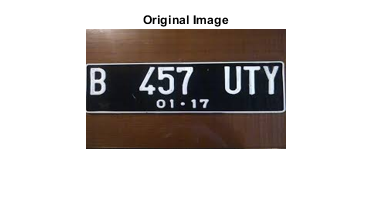

clc;
clear;
close all;

path = 'Plat\';
files = dir([path '/*.jpg']);


%original dan resized
I = imread([path '\' files(1).name]);
I = imresize(I, [120 200]);
figure, imshow(I), title('Original Image');

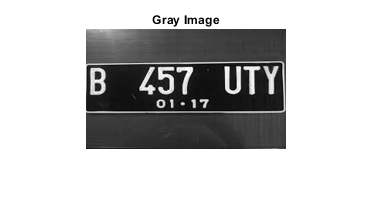


%grayscale
G = rgb2gray(I);
figure, imshow(G), title('Gray Image');

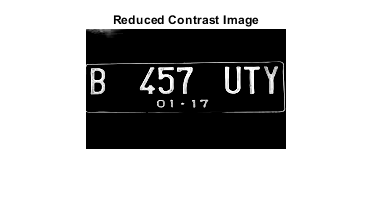


%adjust contrast
G = imadjust(G, [.55 1], []);
G = imadjust(G);
figure, imshow(G), title('Reduced Contrast Image');

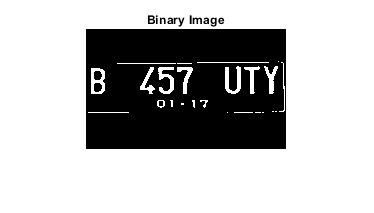


%binerisasi
blocksize = [100 100];
fungsi = @(block_struct) im2bw(block_struct.data, graythresh(block_struct.data));
BW = blockproc(G, blocksize, fungsi);
BW = imclearborder(BW);
figure, imshow(BW), title('Binary Image');

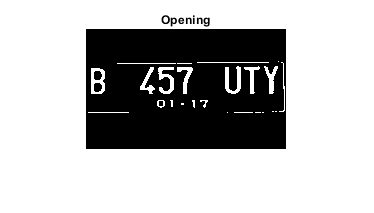


%closing
%BWd = bwmorph(BW, 'close', Inf);
BWd = BW;
figure, imshow(BWd), title('Opening');

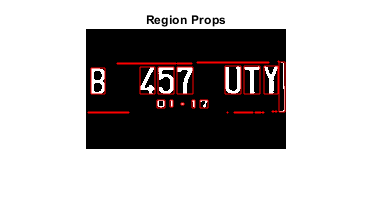


%regionprops
BWr = regionprops(BWd, 'BoundingBox', 'PixelIdxList');
figure, imshow(BWd), title('Region Props');
hold on;

hw = vertcat(BWr(:).BoundingBox);
BWrmv = BWd;
for i=1:size(BWr,1)
    rectangle('Position', BWr(i).BoundingBox,'edgecolor','red');
    if (hw(i, 3)>40 && hw(i,4)>40) || (hw(i, 3)<10  && hw(i,4)<10) || hw(i, 4)<10 || hw(i,4)>40 || hw(i,3)<5 || hw(i,3)>30
        BWrmv(BWr(i).PixelIdxList) = 0;
    end
end

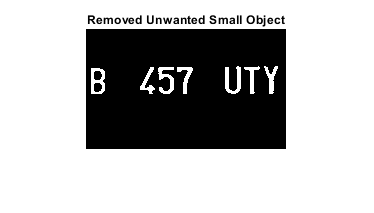

figure, imshow(BWrmv), title('Removed Unwanted Small Object');

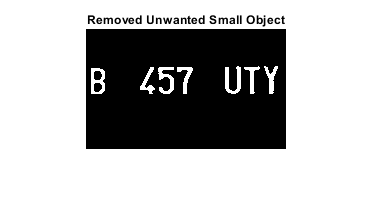


BWr2 = regionprops(BWrmv, 'BoundingBox', 'PixelIdxList');
hw = vertcat(BWr2(:).BoundingBox);
mean_w = sum(hw(:,3))/size(hw,1);
mean_h = sum(hw(:,4))/size(hw,1);

for i=1:size(BWr2, 1)
    if (hw(i,3) < (.9*mean_w) && hw(i,4) < (mean_h)) || hw(i,4) < .9*mean_h
        BWrmv(BWr2(i).PixelIdxList) = 0;
    end
end
BWrmv = imclose(BWrmv, strel('diamond', 1));
figure, imshow(BWrmv), title('Removed Unwanted Small Object');


dir = 'D:\\UNUD TI\\6 - Semester 6\\Machine Learning\\Matlab\\Test_02\\_SegmentedImage\';
S = regionprops(BWrmv, 'BoundingBox', 'Image');
for i=1:size(S,1)
    namafile = strcat('objek',int2str(i),'.jpg');
    imwrite(S(i).Image,strcat(dir,namafile),'jpg');
end

Error using imwrite (line 467)
Unable to open file "D:\\UNUD TI\\6 - Semester 6\\Machine Learning\\Matlab\\Test_02\\_SegmentedImage\objek1.jpg" for writing.  You might not have write permission.